## The Lorenz Attractor

clear
clc
close

sigma = 10; 
beta = 8/3; 
rho = 28;

fun = @(t, x) [sigma * (x(2) - x(1));
            x(1) * (rho - x(3)) - x(2);
            x(1) * x(2) - beta * x(3)];

incond = [0.1 0.1 0.1];
timeint = [0 100];

tau = 0.001;

start_ODE = datetime("now");
[t, xsol] = odeCRK4(fun, timeint, tau, incond);
end_ODE = datetime("now");

time_RKmethod = end_ODE - start_ODE;
time_RKmethod.Format = "hh:mm:ss.SSS"

set(groot, "defaultAxesTickLabelInterpreter", "latex");
set(groot, "defaultTextInterpreter", "latex");
set(groot, "defaultLegendInterpreter", "latex");
set(groot, "defaultColorbarTickLabelInterpreter", "latex");

figure();
scatter3(xsol(:,1), xsol(:,2), xsol(:,3), 4, 1:length(xsol(:, 1)),'filled');
view([-129.8 10.3]);
colormap gray;
colorbar;
axis tight;
grid on;
box on;
xlabel('$x$', 'FontSize', 14);
ylabel('$y$', 'FontSize', 14);
zlabel('$z$', 'FontSize', 14);
title('The Lorenz Attractor', 'FontSize', 16);

% exportgraphics(gcf, "images_png/The_Lorenz_Attractor.png", 'Resolution', 1200)
% exportgraphics(gcf, "images_pdf/The_Lorenz_Attractor.pdf")
% exportgraphics(gcf, "images_eps/The_Lorenz_Attractor.eps")
% save("workspace/TheLorenzAttractor.mat")

## The Lotka—Volterra Attractor

clear
close
clc

a = 2.9851;
b = 3;
c = 2;

fun = @(t, x) [x(1) - x(1) * x(2) + c * x(1) ^ 2 - a * x(3) * x(1) ^ 2;
               - x(2) + x(1) * x(2);
               -b * x(3) + a * x(3) * x(1) ^ 2];

incond = [1 1 1];
timeint = [0 300];

tau = 0.001;

start_ODE = datetime("now");
[t, xsol] = odeCRK4(fun, timeint, tau, incond);
end_ODE = datetime("now");

time_RKmethod = end_ODE - start_ODE;
time_RKmethod.Format = "hh:mm:ss.SSS"

set(groot, "defaultAxesTickLabelInterpreter", "latex");
set(groot, "defaultTextInterpreter", "latex");
set(groot, "defaultLegendInterpreter", "latex");
set(groot, "defaultColorbarTickLabelInterpreter", "latex");

figure();
scatter3(xsol(:,1), xsol(:,2), xsol(:,3), 4, 1:length(xsol(:, 1)),'filled');
view([-48.822 17.712])
colormap gray;
colorbar;
axis tight;
grid on;
box on;
xlabel('$x$', 'FontSize', 14);
ylabel('$y$', 'FontSize', 14);
zlabel('$z$', 'FontSize', 14);
title('The Lotka---Volterra Attractor', 'FontSize', 16);

% exportgraphics(gcf, "images_png/The_Lotka_Volterra_Attractor.png", 'Resolution', 1200)
% exportgraphics(gcf, "images_pdf/The_Lotka_Volterra_Attractor.pdf")
% exportgraphics(gcf, "images_eps/The_Lotka_Volterra_Attractor.eps")
% save("workspace/TheLotkaVolterraAttractor.mat")

## The Aizawa Attractor

clear
close
clc

a = 0.95;
b = 0.7;
c = 0.6;
d = 3.5;
e = 0.25;
f = 0.1;

fun = @(t,x) [(x(3) - b) * x(1) - d * x(2);
               d * x(1) + (x(3) - b) * x(2);
               c + a * x(3) - x(3) ^ 3 / 3 - (x(1) ^ 2 + x(2) ^ 2) * (1 + e * x(3)) + f * x(3) * x(1) ^ 3];

incond = [0.1 0 0];

timeint = [0 300];

tau = 0.001;

start_ODE = datetime("now");
[t, xsol] = odeCRK4(fun, timeint, tau, incond);
end_ODE = datetime("now");

time_RKmethod = end_ODE - start_ODE;
time_RKmethod.Format = "hh:mm:ss.SSS"

set(groot, "defaultAxesTickLabelInterpreter", "latex");
set(groot, "defaultTextInterpreter", "latex");
set(groot, "defaultLegendInterpreter", "latex");
set(groot, "defaultColorbarTickLabelInterpreter", "latex");

figure();
scatter3(xsol(:,1), xsol(:,2), xsol(:,3), 4, 1:length(xsol(:, 1)),'filled');
view([-40.90 15.09]);
colormap gray;
colorbar;
axis tight;
grid on;
box on;
xlabel('$x$', 'FontSize', 14);
ylabel('$y$', 'FontSize', 14);
zlabel('$z$', 'FontSize', 14);
title('The Aizawa Attractor', 'FontSize', 16);

% exportgraphics(gcf, "images_png/The_Aizawa_Attractor.png", 'Resolution', 1200)
% exportgraphics(gcf, "images_pdf/The_Aizawa_Attractor.pdf")
% exportgraphics(gcf, "images_eps/The_Aizawa_Attractor.eps")
% save("workspace/TheAizawaAttractor.mat")

## The Tamari Attractor

clear
clc
close

a = 1.013;
b = -0.011;
c = 0.02;	
d = 0.96;
e = 0.0;
f = 0.01;
g = 1.0;
h = 0.05;
u = 0.05;

fun = @(t,x) [(x(1) - a * x(2)) * cos(x(3)) - b * x(2) * sin(x(3));
              (x(1) + c * x(2)) * sin(x(3)) + d * x(2) * cos(x(3));
               e + f * x(3)+ g * atan((1 - u) / (1 - h) * x(1) * x(2))];

incond = [1 1 1];
timeint = [0 500];

tau = 0.001;

start_ODE = datetime("now");
[t, xsol] = odeCRK4(fun, timeint, tau, incond);
end_ODE = datetime("now");

time_RKmethod = end_ODE - start_ODE;
time_RKmethod.Format = "hh:mm:ss.SSS"

time_RKmethod = duration
   00:00:04.344


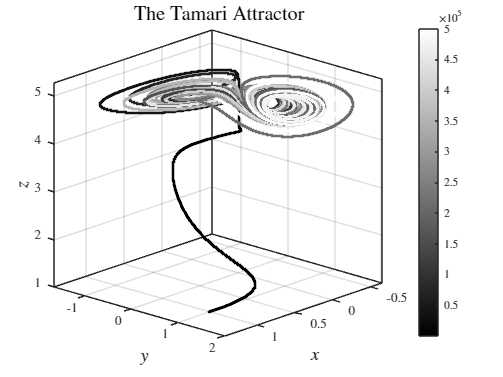

set(groot, "defaultAxesTickLabelInterpreter", "latex");
set(groot, "defaultTextInterpreter", "latex");
set(groot, "defaultLegendInterpreter", "latex");
set(groot, "defaultColorbarTickLabelInterpreter", "latex");

figure();
scatter3(xsol(:, 1), xsol(:, 2), xsol(:, 3), 4, 1:length(xsol(:, 1)), 'filled');
view([-227.35 19.42])
colormap gray;
colorbar;
axis tight;
grid on;
box on;
xlabel('$x$', 'FontSize', 14);
ylabel('$y$', 'FontSize', 14);
zlabel('$z$', 'FontSize', 14);
title('The Tamari Attractor', 'FontSize', 16);

% exportgraphics(gcf, "images_png/The_Tamari_Attractor.png", 'Resolution', 1200)
% exportgraphics(gcf, "images_pdf/The_Tamari_Attractor.pdf")
% exportgraphics(gcf, "images_eps/The_Tamari_Attractor.eps")

% save("workspace/TheTamariAttractor.mat")

## The Halvorsen Attractor

clear
close
clc

a = 1.4;

fun = @(t, x) [ - a * x(1) - 4 * x(2) - 4 * x(3) - x(2) ^ 2;
                - a * x(2) - 4 * x(3) - 4 * x(1) - x(3) ^ 2;
                - a * x(3) - 4 * x(1) - 4 * x(2) - x(1) ^ 2];

incond = [1 0 0];
timeint = [0 300];

tau = 0.001;

start_ODE = datetime("now");
[t, xsol] = odeCRK4(fun, timeint, tau, incond);
end_ODE = datetime("now");

time_RKmethod = end_ODE - start_ODE;
time_RKmethod.Format = "hh:mm:ss.SSS"

time_RKmethod = duration
   00:00:02.582


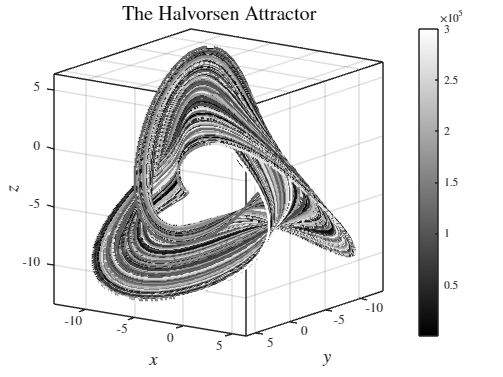

set(groot, "defaultAxesTickLabelInterpreter", "latex");
set(groot, "defaultTextInterpreter", "latex");
set(groot, "defaultLegendInterpreter", "latex");
set(groot, "defaultColorbarTickLabelInterpreter", "latex");

figure();
scatter3(xsol(:, 1), xsol(:, 2), xsol(:, 3), 4, 1:length(xsol(:, 1)), 'filled');
view([324.4 -13.7])
colormap gray;
colorbar;
axis tight;
grid on;
box on;
xlabel('$x$', 'FontSize', 14);
ylabel('$y$', 'FontSize', 14);
zlabel('$z$', 'FontSize', 14);
title('The Halvorsen Attractor', 'FontSize', 16);

% exportgraphics(gcf, "images_png/The_Halvorsen_Attractor.png", 'Resolution', 1200)
% exportgraphics(gcf, "images_pdf/The_Halvorsen_Attractor.pdf")
% exportgraphics(gcf, "images_eps/The_Halvorsen_Attractor.eps")
% save("workspace/TheHalvorsenAttractor.mat")

## The Thomas Attractor

clear
close
clc

b = 0.19;

fun =  @(t,x) [ - b * x(1) + sin(x(2));
                - b * x(2) + sin(x(3));
                - b * x(3) + sin(x(1))];

incond = [0.1 0 0];
timeint = [0 500];

tau = 0.001;

start_ODE = datetime("now");
[t, xsol] = odeCRK4(fun, timeint, tau, incond);
end_ODE = datetime("now");

time_RKmethod = end_ODE - start_ODE;
time_RKmethod.Format = "hh:mm:ss.SSS"

time_RKmethod = duration
   00:00:04.117


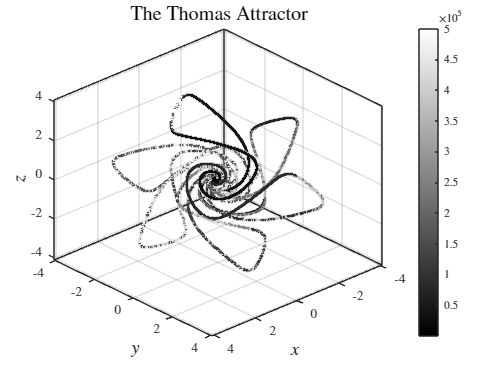

set(groot, "defaultAxesTickLabelInterpreter", "latex");
set(groot, "defaultTextInterpreter", "latex");
set(groot, "defaultLegendInterpreter", "latex");
set(groot, "defaultColorbarTickLabelInterpreter", "latex");

figure();
scatter3(xsol(:, 1), xsol(:, 2), xsol(:, 3), 4, 1:length(xsol(:, 1)), 'filled');
view([137.07 33.23])
colormap gray;
colorbar;
axis tight;
grid on;
box on;
xlabel('$x$', 'FontSize', 14);
ylabel('$y$', 'FontSize', 14);
zlabel('$z$', 'FontSize', 14);
title('The Thomas Attractor', 'FontSize', 16);

% exportgraphics(gcf, "images_png/The_Thomas_Attractor.png", 'Resolution', 1200)

% exportgraphics(gcf, "images_pdf/The_Thomas_Attractor.pdf")
% exportgraphics(gcf, "images_eps/The_Thomas_Attractor.eps")
% save("workspace/TheThomasAttractor.mat")